# Viewing Mismatched Filters With and Without Spoiling

clear; close all

## Chip Sequence

chipSeqBarker = [1 1 1 1 1 -1 -1 1 1 -1 1 -1 1]'; % Barker 13
chipSeqBarker =repmat(chipSeqBarker,1,3).';
chipSeqBarker = chipSeqBarker(:);

nsamp = 20;
chipSeqRand = exp(1i*2*pi*rand(nsamp,1));
chipSeqRand =repmat(chipSeqRand,1,2).';
chipSeqRand = chipSeqRand(:);

chipSeq = chipSeqBarker; % CHANGE BETWEEN chipSeqRand and chipSeqBarker
K = numel(chipSeq); % K chips

## Matched Filter

[mf,psl,isl,lag] = getNormalizedAC(chipSeq,chipSeq);
fprintf('Matched Filter: PSL: %f  ISL: %f\n',psl,isl)

Matched Filter: PSL: -22.278867  ISL: -11.487055


## Create Inputs for Least Squares (LS)

M = 4*K; % M taps in FIR filter. Should be >= K

% Create ideal response for LS computation
% Index of peak in ideal response
if mod(M+K,2) == 0 % M is even
    p = (M+K)/2;
else
    p = (M+K-1)/2; % M is odd
end

% Ideal response vector
% All zeros except "middle" element is 1
d = zeros(M+K,1);
d(p) = 1;

% Banded Matrix C
C = zeros(K+M,M);
for m = 1:M
    C((1:K)+m-1, m) = chipSeq(:);
end

## LS Solution fo MMF

Perform LS computation

% z = inv(C'*C)*C'*d; % Easy to read computation
z = (C'*C)\(C'*d);    % Recommended workflow in MATLAB

[mmf,psl,isl] = getNormalizedAC(z,chipSeq);
fprintf('Mismatched Filter: PSL: %f  ISL: %f\n',psl,isl)

Mismatched Filter: PSL: -36.141635  ISL: -19.191974


xvals = -ceil(numel(mmf)/2-1):floor(numel(mmf)/2);

## MMF with Beam Spoiling

Implementation of the paper: Practical Aspects of Optimal Mismatch Filtering and Adaptive Pulse Compression for FM Waveforms by Dakota Henke

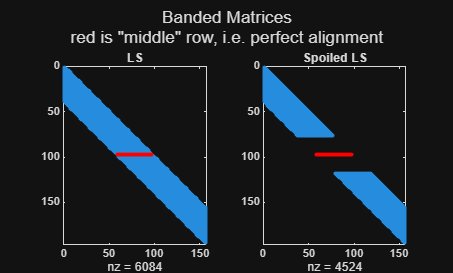

spoilN = 20; % Number of spoiled rows above and below "middle" row
[zSpoil, CSpoil] = getSpoiledFilter(spoilN,C,p,M,d);
plotBandedMats(C,CSpoil,p);


[mmfSpoil,psl,isl] = getNormalizedAC(zSpoil,chipSeq);
fprintf('Spoiled Mismatched Filter: PSL: %f  ISL: %f\n',psl,isl)

Spoiled Mismatched Filter: PSL: -17.090490  ISL: -10.331855


## Animation Plot

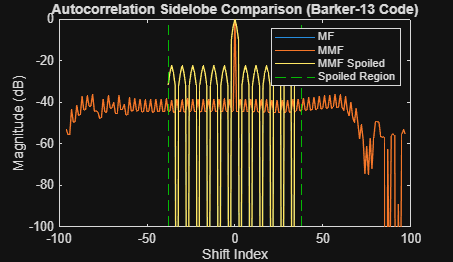

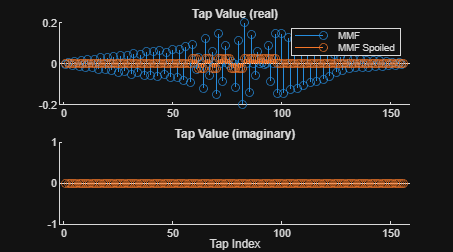

f1 = figure;
f1.Position(3:4) = [950,550];
ax1 = gca;
mfPlot = plot(ax1,lag,mf,'DisplayName','MF');
hold(ax1,'on')
mmfPlot = plot(ax1,xvals,mmf,'DisplayName','MMF');
xlabel(ax1,'Shift Index')
ylabel(ax1,'Magnitude (dB)')
ylim(ax1,[-100 0])
if numel(chipSeqBarker) == numel(chipSeq) && all(chipSeqBarker == chipSeq)
    title(ax1,'Autocorrelation Sidelobe Comparison (Barker-13 Code)')
else
    title(ax1,'Autocorrelation Sidelobe Comparison (Random Polyphase Code)')
end
vertLines = xline(ax1,NaN*[-1 1],'DisplayName','Spoiled Region','Color','green','LineStyle','--');


f2 = figure;
f2.Position(3:4) = [900,500];
ax21 = subplot(2,1,1);
title(ax21,'Tap Value (real)')
hold(ax21,'on')
stem(ax21,real(z),'DisplayName','MMF')
ax22 = subplot(2,1,2);
hold(ax22,'on')
stem(ax22,imag(z),'DisplayName','MMF')
title(ax22,'Tap Value (imaginary)')
xlabel('Tap Index')

for ii = 0:38
    if ii == 0
        mmfsPlot = plot(ax1,xvals,mmf,'DisplayName','MMF Spoiled');
        legend(ax1,[mfPlot,mmfPlot,mmfsPlot,vertLines(1)])
        spoliedTapsReal = stem(ax21,real(z),'DisplayName','MMF Spoiled');
        spoliedTapsImag = stem(ax22,imag(z),'DisplayName','MMF Spoiled');
        legend(ax21)
    else
        zSpoil =  getSpoiledFilter(ii,C,p,M,d);
        [mmfSpoil,psl,isl] = getNormalizedAC(zSpoil,chipSeq);
        mmfsPlot.YData = mmfSpoil;
        vertLines(1).Value = -ii;
        vertLines(2).Value = ii;
        spoliedTapsReal.YData = real(zSpoil);
        spoliedTapsImag.YData = imag(zSpoil);
    end
    pause(.2)
end

## Helper Functions

function [ac,psl,isl,lag] = getNormalizedAC(z,chipSeq)
    if isequal(size(z), size(chipSeq)) && all(z == chipSeq)
        [ac,lag] = xcorr(chipSeq);
    else
        ac = conv(z,chipSeq);
    end
    ac = mag2db(abs(ac));
    ac = ac - max(ac);
    [psl,isl] = sidelobelevel(ac);
end

function [z,Cspoil] =  getSpoiledFilter(spoilN,Cspoil,p,M,d)
    Cspoil(p+(1:spoilN),:) = 0;
    Cspoil(p-(1:spoilN),:) = 0;

    % LS Solution
    delta = .01; % diagonal weighting
    % z = inv(Cspoil'*Cspoil + delta*eye(M))*Cspoil'*d; 
    z = (Cspoil'*Cspoil + delta*eye(M)) \ (Cspoil'*d); % recommended MATLAB workflow
end

function plotBandedMats(C,CSpoil,p)
    figure; 
    ax1 = subplot(1,2,1); spy(C)
    xlabelString = ax1.XLabel.String;
    hold on
    C(1:p-1,:) = 0;
    C(p+1:end,:) = 0;
    spy(C,'r')
    xlabel(xlabelString);
    title('LS')

    ax2 = subplot(1,2,2); spy(CSpoil);
    xlabelString = ax2.XLabel.String;
    hold on
    CSpoil(1:p-1,:) = 0;
    CSpoil(p+1:end,:) = 0;
    spy(CSpoil,'r')
    xlabel(xlabelString);
    title('Spoiled LS')
    
    sgtitle({'Banded Matrices','red is "middle" row, i.e. perfect alignment'})    
end